# Proyecto final

Diseño de una red de sensores inalámbrica para la detección de personas en distintos puntos de la Universidad del Norte

**Presentado por: **Juan Menco, Arturo Pantoja & Jesús Quintero

**Parámetros de diseño:**

- Características de la tecnología a usar (MICAz): potencia de transmisión, sensibilidad, banda de frecuencia, tasa de transmisión, modulación, rango

- Consumo de energía: *implementación de protocolos de único salto o mútiples saltos, *sensor utilizado

- Cuál protocolo de capa MAC y de enrutamiento en base al punto anterior

- Representación de los datos obtenidos por el sensor

**Características de la red:**

- Las mediciones se hacen en un total de 14 espacios, en los que hay un nodo "padre". Todos los "padres" se comunican con un único Gateway.

- Se emplea un protocolo 

**Características de la tecnología MICAz**

micaz.pTx = [-24 0];        % Potencia de transmisión (dB)
micaz.pRx = [-94 -90];      % Sensibilidad del receptor (dB)
micaz.rango = [75 100];     % Rango de cobertura (m)
micaz.dr = 250;             % Data rate (kbps)
micaz.banda = [2.4 2.4835]; % Banda de frecuencia (GHz)

**Ubicación de los nodos y el Gateway**

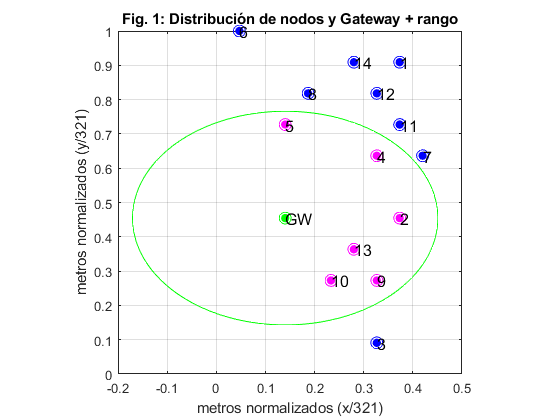

area = [ 0 135 135 0 ; 0 0 321 321 ];   % Coordenadas del área
areanorm = area/321;                    % Área de trabajo normalizada

gdx = max(areanorm(1,:))/9;             % Grilla horizontal x9
gdy = max(areanorm(2,:))/11;            % Grilla vertical x11

% Coordenadas de los nodos y el Gateway dentro de una cuadrícula 9x11
coord = [
    3*gdx,5*gdy,[0 1 0];    % 0. Gateway
    8*gdx,10*gdy,[0 0 1];   % 1.
    8*gdx, 5*gdy,[0 0 1];   % 2.
    7*gdx, 1*gdy,[0 0 1];   % 3.
    7*gdx, 7*gdy,[0 0 1];   % 4.
    3*gdx, 8*gdy,[0 0 1];   % 5.
    1*gdx, 11*gdy,[0 0 1];  % 6.
    9*gdx, 7*gdy,[0 0 1];   % 7.
    4*gdx, 9*gdy,[0 0 1];   % 8.
    7*gdx, 3*gdy,[0 0 1];   % 9.
    5*gdx, 3*gdy,[0 0 1];   % 10.
    8*gdx, 8*gdy,[0 0 1];   % 11.
    7*gdx, 9*gdy,[0 0 1];   % 12.
    6*gdx, 4*gdy,[0 0 1];   % 13.
    6*gdx, 10*gdy,[0 0 1];  % 14.
    ];

% Distancias de los nodos al Gateway
x0 = coord(1,1);
y0 = coord(1,2);
d = zeros(1,length(coord(:,1))-1);
for i = 2 : length(coord(:,1))
    dx = abs(coord(i,1)-x0);
    dy = abs(coord(i,2)-y0);
    d(i-1) = sqrt(dx^2+dy^2)*321;
end

% Rango del Gateway
idch = find(d<=100)+1;
coord(idch,3) = 1;
coord(idch,4) = 0;
coord(idch,5) = 1;

% Distribución de los nodos
cla
sc2 = scatter(coord(:,1),coord(:,2),40,coord(:,3:end),'filled');
hold('on')
sc3 = scatter(coord(:,1),coord(:,2),80,coord(:,3:end));
title('Fig. 1: Distribución de nodos y Gateway + rango')
xlabel('metros normalizados (x/321)')
ylabel('metros normalizados (y/321)')
axis('square')
id = {'GW','1','2','3','4','5','6','7','8','9','10','11','12','13','14'};
text(coord(:,1),coord(:,2),id,'FontSize',12)
box('on'), grid('on')

% Rango de alcance del Gateway (GW)
syms theta
radio = 100/321;
x1 = x0 + radio*cos(theta);
y1 = y0 + radio*sin(theta);
fc1 = fplot(x1,y1,'g-','LineWidth',1);
hold('off')

**Topología y protocolo de enrutamiento**

Asumimos:

- Los nodos son estáticos

- Los nodos saben dónde están ubicados

- Los nodos usan la misma potencia de Tx pero el consumo de energía no es uniforme

El primer acercamiento se basa en el protocolo DDCH (Density and Distance based Cluster Head Selection) para la detección de cabezas de cluster en la red [1].

Las cabezas de cluster en este caso se escogerán entre los nodos que se encuentran en el rango del Gateway, y los cluster serán conformados por los nodos más cercanos a cada cabeza de cluster.

Entonces en este caso hay 6 posibles cabezas de cluster, como se muestra en la Fig. 1.

A continuación se calculan las distancias desde cada nodo lejano al Gateway (NLG) a cada nodo cercano al Gateway (NCG) o posible cabeza de cluster.

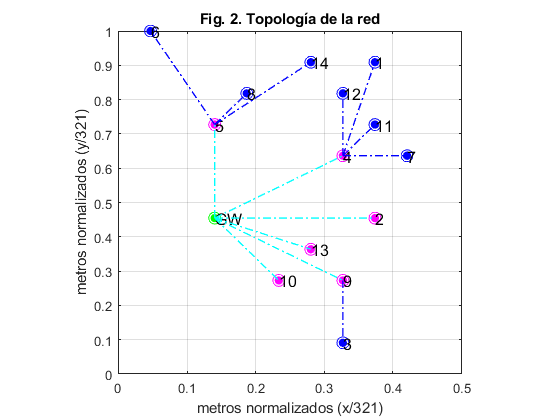

% Nodos Cercanos al Gateway (NGC)
NCG = idch;                             % ID del nodo
NCGxy = coord(NGC,[1 2]);               % Coordenadas (x,y) del nodo

% Nodos Lejanos al Gateway (NLG)
NLG = find(d>100);                        % ID del nodo
NLGxy = coord(NLG+1,[1 2]);               % Coordenadas (x,y) del nodo

% Distancias
D = zeros(length(NCG),length(NLG));
for i = 1 : length(NCG)
    D(i,:) = distancia(NLGxy,NCGxy(i,:));
end

% Mínimas distancias
Dmin = zeros(2,length(D(1,:)));
for i = 1 : length(Dmin)
    Dmin(1,i) = min(D(:,i));                % Distancia
    Dmin(2,i) = NCG(D(:,i) == Dmin(1,i))-1; % Cluster Head
end

% Cluster nodes
cNodes = {4,length(NLG)};
for i = 1 : length(NCG)
    cNodes{1,i} = NCG(i)-1;                     % Cluster Head ID
    cNodes{2,i} = NCGxy(i,:);                   % Cluster Head (x,y)
    cNodes{3,i} = NLG(Dmin(2,:) == NCG(i)-1);   % Cluster Nodes ID
    if ~isempty(cNodes{3,i})
        for j = 1 : length(cNodes{3,i})
            k = NLGxy(NLG == cNodes{3,i}(j),:);
            cNodes{4,i}(j,:) = k;
        end
    end
end

% Gráfica
cla
sc4 = scatter(coord(:,1),coord(:,2),40,coord(:,3:end),'filled');
hold('on')
sc5 = scatter(coord(:,1),coord(:,2),80,coord(:,3:end));
title('Fig. 2. Topología de la red')
xlabel('metros normalizados (x/321)')
ylabel('metros normalizados (y/321)')
axis('square')
id = {'GW','1','2','3','4','5','6','7','8','9','10','11','12','13','14'};
text(coord(:,1),coord(:,2),id,'FontSize',12)
box('on'), grid('on')

% NCG -> Gateway
for i = 1 : length(NCG)
    xx = [coord(1,1) cNodes{2,i}(1)];
    yy = [coord(1,2) cNodes{2,i}(2)];
    line(xx,yy,'LineStyle','-.','Color',[0 1 1],'LineWidth',1)
end

% NCG -> NLG (cluster)
for i = 1 : length(NCG)
    if ~isempty(cNodes{3,i})
        for j = 1 : length(cNodes{3,i})
            xx = [cNodes{2,i}(1) cNodes{4,i}(j,1)];
            yy = [cNodes{2,i}(2) cNodes{4,i}(j,2)];
            line(xx,yy,'LineStyle','-.','Color',[0 0 1],'LineWidth',1)
        end        
    end
end
hold('off')

**Análisis de potencia en los enlaces**

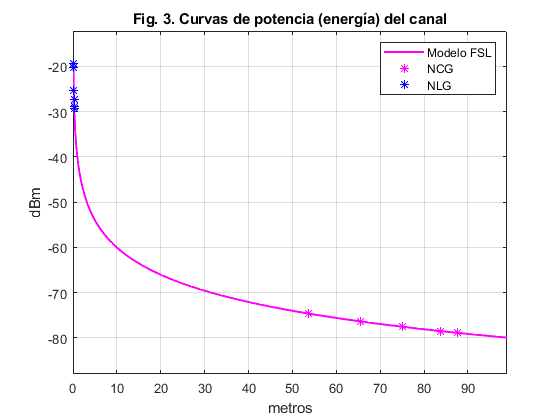

% Pérdidas en el espacio libre (FSL)
% FSL = (4*pi*d/lambda)^2
f = micaz.banda(1)*10^9;        % Banda de frecuencia: 2.4 GHz
c = 299792458;                  % Velocidad de la luz en el vacío (m/s)
lambda = c/f;                   % Longitud de onda
NCGfsl = 10*log10((4*pi*d(idch-1)/lambda).^2);
NLGfsl = 10*log10((4*pi*Dmin(1,:)/lambda).^2);

ptx = micaz.pTx(2);             % Potencia de transmisión: Ptx = 0 dBm
prxGW = ptx - NCGfsl;           % Potencia recibida por el Gateway (dBm)
prxCH = ptx - NLGfsl;           % Potencia recibida por las cabezas de 
                                % cluster (dBm)

% Pérdidas en el canal vs. distancia
cla

syms dfsl
pfsl1 = ptx - 10*log10((4*pi*dfsl/lambda).^2);
p1 = fplot(pfsl1,[0 max(d)],'Color','m','LineWidth',1.5);
hold('on'), grid('on')

sc6 = scatter(d(idch-1),prxGW,'m*');
sc7 = scatter(Dmin(1,:),prxCH,'b*');

hold('off')
title('Fig. 3. Curvas de potencia (energía) del canal')
xlabel('metros')
ylabel('dBm')

xlim([0.0 98.9])
ylim([-88.0 -12.2])
legend('Modelo FSL', 'NCG', 'NLG')

**Información a transmitir (header + datos del sensor + CRC)**

*Ver función: nodeObj.m*

La data transmitida por los nodos tiene 3 partes:

- **Encabezado (12+ bits):** Contiene un identificador de nodo creado a partir del número de nodo *¿y si es o no cabeza de cluster?*.

- **Payload (50 bits):** Contiene la información del sensor. Como el objetivo es simular el comportamiento de la red, el payload es un conjunto aleatorio de 50 bits uniformemente distribuido. Los nodos genera la secuencia cada vez que hay un periodo de muestreo o recolección de data.

- **CRC (13 bits): **Contiene los bits para la detección de errores.

nodos = cell(1,14);
for i = 1 : 15
    nodos{1,i} = nodeObj(i);
    gateway.divisor(i,:) = nodeObj(i).divisor;
end

**Protocolo de capa MAC: UCSMA-Probabilistic Polling**

Se pretende hacer uso de este protocolo porque no es necesario definir ventanas de transmisión y recepción para los nodos, si no que cuando un nodo tenga toda la data entonces la transmite.

Esto nos sirve también porque el periodo de muestreo de los nodos es relativamente largo (25 segundos).

La idea es que dado un tiempo inicial `t0` cada nodo haga el muestreo de la zona `25 s `después  y envíe la info una vez que tenga los `50 bits` de datos planteados en la sección anterior.

Para enviar los datos se debe primero recibir un *Polling Packet (PP) *que contiene un valor de referencia que se compara con uno calculado por cada nodo. Si el valor calculado por el nodo es mayor que el del `PP`, el nodo espera un tiempo aleatorio para revisar el canal, y si está libre entonces transmite.

Tanto el `PPn` (valor calculado en el nodo que se compara con el `PP`), y el tiempo aleatorio `tk` que espera para revisar el canal, son números aleatorios undependientes uniformemente distribuidos.

El valor de `PP `se calcula dinámicamente de acuerdo al número de paquetes dañados recibidos. Si hay colisiones (paquetes dañados o perdidos) se reduce el valor `PP `de forma aditiva, es decir, se le resta un valor `epsilon`. En el caso que no se reciban datos, el valor `PP` aumenta de tal forma que sea más probable que el valor calculado en los nodos sea mayor a `PP `y así más paquetes se envíen. En este caso `PP `aumenta en un factor `phi` tal que: $\mathrm{PP}<\phi \;\mathrm{PP}<1$.

Para revisar el canal, se usa un método basado en potencia de la señal en el canal. Si la potencia en el canal es mayor a un valor de referencia entonces no se transmite: $P^{\mathrm{CS}} \left(N_i \right)>P_{\mathrm{th}}$.

`Pth` es la potencia de referencia, y el valor que se le de es porporcional al número de colisiones posibles en la transmisión. Se pretende obtener un valor para `Pth `luego de hacer el análisis de potencia transmitida en cada enlace. La potencia en el canal se modelará con el esquema de pérdidas en el espacio libre.

*Problemas: *puede ocurrir el caso de estación escondida en el que un nodo ve el canal libre pero en realidad está siendo usado por otro que no se encuentra en su rango.

**Flujograma para UCSMA-PP**